## Portfolio of Completely Independent Processes of Identical p

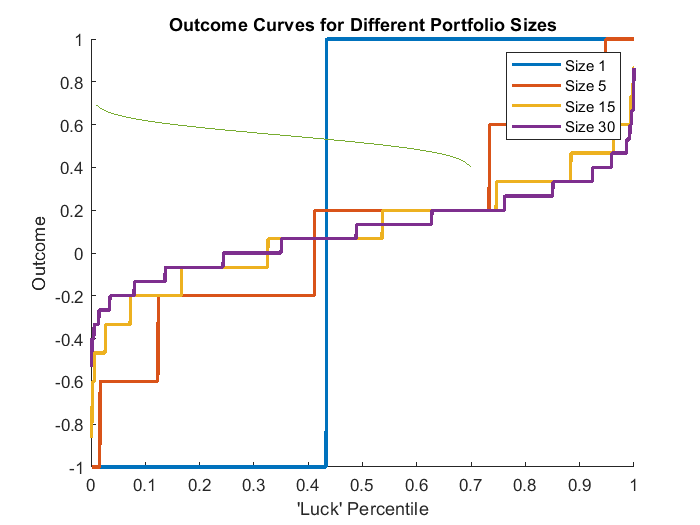

num_trials = 1000;
p = .55;

figure
hold on
for portfolio_size = [1 5 15 30]
    outcomes = zeros(1,num_trials);
    for trial_number = 1:num_trials
        dice_rolls = rand(1,portfolio_size);
        outcomes(trial_number) = sum(2*(dice_rolls<p)-1)/portfolio_size; % 55% chance of doubling your money
    end
    outcomes = sort(outcomes);
    plot((1:num_trials)/num_trials,outcomes,'LineWidth',2)
end

plot((.01:.01:.99),erfcinv((.01:.01:.99)*2*sqrt(2))*sqrt(.45*.55)/sqrt(30)+.55);
legend_labels = cell(1,length([1 5 15 30]));
counter = 1;
for legend_label_number = [1 5 15 30]
    legend_labels{counter} = sprintf('Size %d',legend_label_number);
    counter = counter + 1;
end
legend(gca,legend_labels)

title('Outcome Curves for Different Portfolio Sizes')
xlabel('''Luck'' Percentile')
ylabel('Outcome')


% My Idea: Smoothness of Curve -> More of an Investment
%          Choppiness of Curve -> More of a Gamble

% Also, Investment requires that Expected Value is above 0
% Would be interesting if investment requires a given Expected Value to
% Standard Deviation Ratio